# NOT FINISHED MODEL

## Input runData and modelData

tic
clear runData modelData;
runData.filename = 'testgif.gif';
runData.runType = 'time';
runData.oneGroup = true;
runData.adjointFlag = false; % --> ???
runData.checkGeometry = true;
runData.plotSolution = true;
runData.hmax = 0.20;          % mesh size: default hmax = 0.05
% Cross section settings
runData.dataset = 'DiffTemp_driven';  
runData.group = 1;          % --> delete: group number to use for the cross-sections, must be one in this case, since only one type/group/NP (nGroups is also 1)
runData.nEquations = 2;

% Load material properties and sources
[modelData.Diff,modelData.Diff_info,modelData.Heat,modelData.Heat_info] = c4_DiffHeat(runData.dataset);
% Material assignment to model domains
modelData.materialIDs = [1,2,2]; % define differently if different material per face (# faces = 3, so 3 elements)

% Source assignment to model domains
modelData.sourceIDs = [1,2,2]; % define differently if different source term (more heat /concentration)
modelData.fixedSource = [6.2*10^(-4)*60;5.0*10^(-3)*60;5.0*10^(-3)]; % Source terms, is equal to metabolic heat for each subdomain. Change if different source terms. 
modelData.seedheat = 10*1.066*60; % specific heating power = SAR * density absorbing material (breast) = 1066 kg/m3, to reach T of 50 *C, SAR must be higher than ~3 W/g 
                                % *60 to compensate for min instead of s
                                % --> SAR * rho * s/min
modelData.SourceValue = 1.19*10^13*0.10; % maxiumum possible #NPs/injection; % #/injection concentration of NPs per injection volume ~1.25E+12 #NPs/injection

## Create model, geometry and mesh

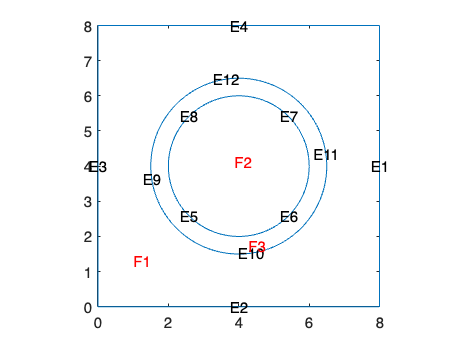

% Create PDE model
[model,modelData] = s1_createPDEModel(runData,modelData);
% Load test geometry
[model,~,centretumor,diametertumor] = t2_createGeometry2D(model,runData);

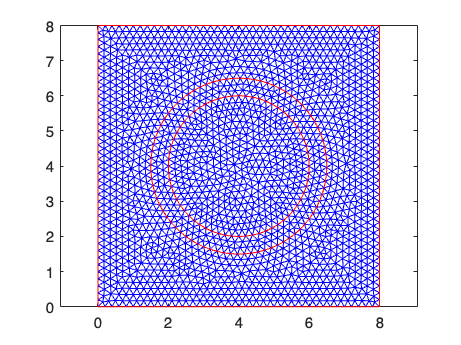

% Generate mesh
[model] = s3_createMesh2D(model,runData);

toc

Elapsed time is 2.284255 seconds.


## Set BC, IC and time scale

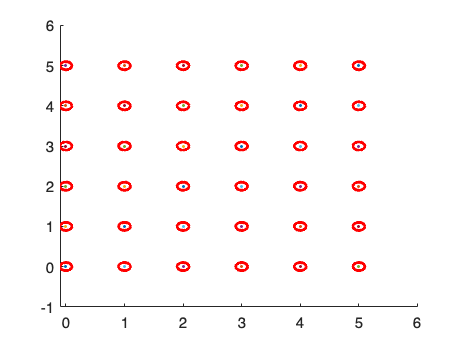

noSeeds = 9

tic
% Boundary conditions:      only applicable for outer boundaries (no information on volume outside control volume)
runData.nBCs.neumann = 1;   % necessary to define if multiple neumann boundaries with different values
runData.BCs.neumann(1) = struct('edge',1:4,'q',[0 0; 0 modelData.Heat(1).wtcb],'g',[0; modelData.Heat(1).Tbwtcb]); % flux breast [#NPs/m2*s] % must depend on conc. present to not become negative. Which BC?
runData.nBCs.dirichlet = 1;
runData.BCs.dirichlet(1) = struct('edge',[],'u',(273.15+37));     % [] means isempty

% Initial conditions
[modelData.x0, modelData.y0, noSeeds] = t4_3_XZ_seedlocationssquare(diametertumor,centretumor);

runData.nICs = 2;                  % necessary to define if multiple initial conditions different per face
modelData.Tinit = 310.15;     % temperature breast tissue
modelData.Cinit_tumor = @(location)Cinit_NP2(location,modelData.x0,modelData.y0,modelData.SourceValue);
modelData.initF1 = [0; modelData.Tinit];
%modelData.initF23 = [2000; modelData.Tinit];

runData.IC(1) = struct('u',modelData.initF1,'Face',1);   % initial concentration and temperature in body and tumour. Initial concentration of NPs in body = 0 [#NPs/m3]
runData.IC(2) = struct('u',modelData.Cinit_tumor,'Face',2:3);    % initial concentration of NPs in tumor: equation zero everywhere but at injection locations [#NPs/m3]

% Time scale
m = 1*30; % number of minutes = (days)*(hours/day)*(min/hour)
runData.timePoints = 0:0.1:m;  % start time : timestep : end time

[model] = s4_2_loadBCIC(model,modelData,runData);
toc

Elapsed time is 0.489291 seconds.


## Solve system of PDE 

date = datestr(now, 'HH:MM')

date = '13:03'

tic
% Solve PDE model: Combined model of Diffusion and Heat distribution over time
[~,results] = c5_NPDiffHeat2D(model,modelData,runData);
toc

Elapsed time is 104.117560 seconds.


## Results: Material and temperature spread over time

modelData.Tresults = results.NodalSolution(:,2,:) - 273.15;
modelData.Cresults = results.NodalSolution(:,1,:);
Tresults = results.NodalSolution(:,2,:) - 273.15;
Cresults = results.NodalSolution(:,1,:);

##  Results and plots: temperature and concentration

Input variables:
SAR = 35 W/g
Planning target values


averageT = 169.0712

minT = -6.9230

maxT = 1.3148e+03

medianT = 37.0004

modeT = -6.9230

Input variables:
SAR = 35 W/g
Planning target values


averageT = 1.1831e+09

minT = -2.0961e+09

maxT = 1.6182e+10

medianT = 1.6594e+04

modeT = -2.0961e+09

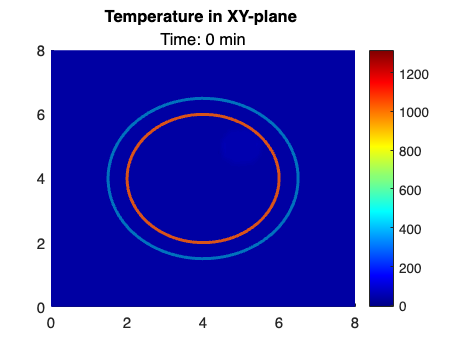

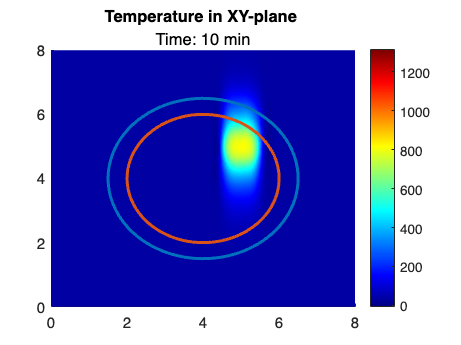

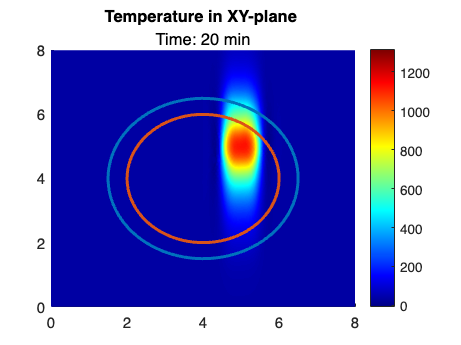

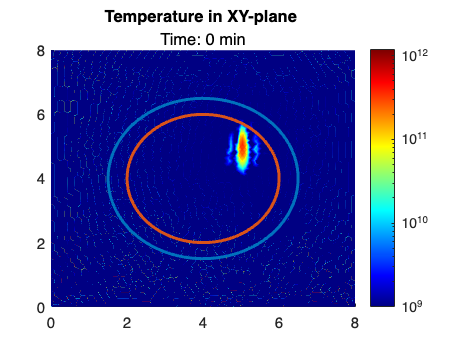

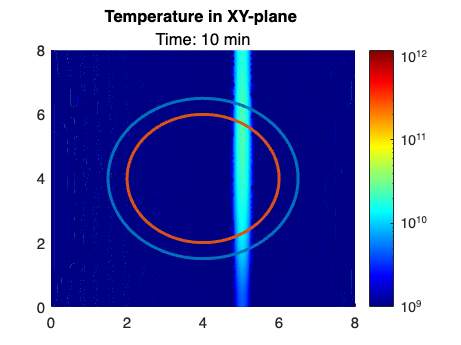

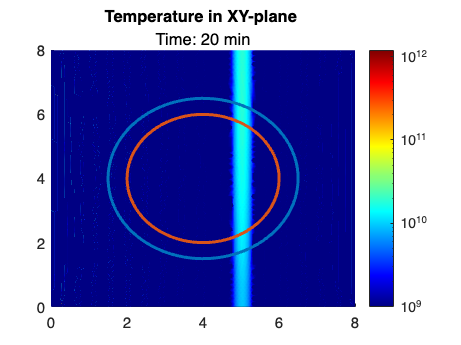

[model] = c6_results2D(model,modelData,runData);

function Cinit_tumor = Cinit_NP2(location,x0,y0,SourceValue)
        % heaviside gives 0 if the equation of radius - the circle is smaller than 0 (location is outside the circle)
        % and gives 1*Sourcevalue for all locations within the circle
        % third term represents a normal distribution over x and y, resulting in a smooth distribution
        % with the coordinations of the node as the maximum of the Gaussian peak (=1).
        % This needs to be multiplied with the value of the concentration of the injection
        r = 0.1;            % radius that the seed should have
        Cinit_t = 0;
        for i = 1:length(x0)
        Cinit_t = (heaviside((r^2)-((location.x-x0(i)).^2+(location.y-y0(i)).^2))).*SourceValue;
        end  
        M = length(Cinit_t);
        Cinit_tumor = zeros(2,M);
        Cinit_tumor(1,:) = Cinit_t;
        Cinit_tumor(2,:) = 310.15;
        % SOME FIST RULES:
        % 1. Smaller diameter seed: smaller sigma, smaller radius IC, (larger caxis: visibility)
        % 2. Smaller solmin: smaller Hmax, smaller stepsize, smaller sigma
        % 3. Stepsize and hmax dont have influence on diameter seed
        % 4. Sigma cannot be smaller than Hmax, because spread cannot be smaller than mesh element
        % 5. 
end